# Cantera Test Examples for Matlab

LoadCantera

Cantera is ready for use


clear all
close all
cleanup

  equil A chemical equilibrium example.
 
  This example computes the adiabatic flame temperature and equilibrium
  composition for a methane/air mixture as a function of equivalence ratio.



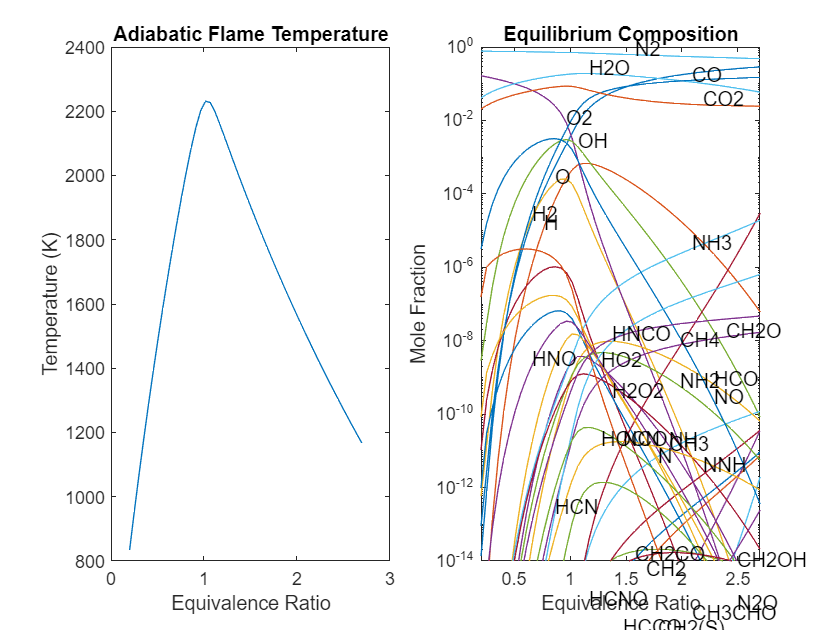

Elapsed time is 5.712092 seconds.


equil();

  isentropic  isentropic, adiabatic flow example
 
     In this example, the area ratio vs. Mach number curve is
     computed for a hydrogen/nitrogen gas mixture.



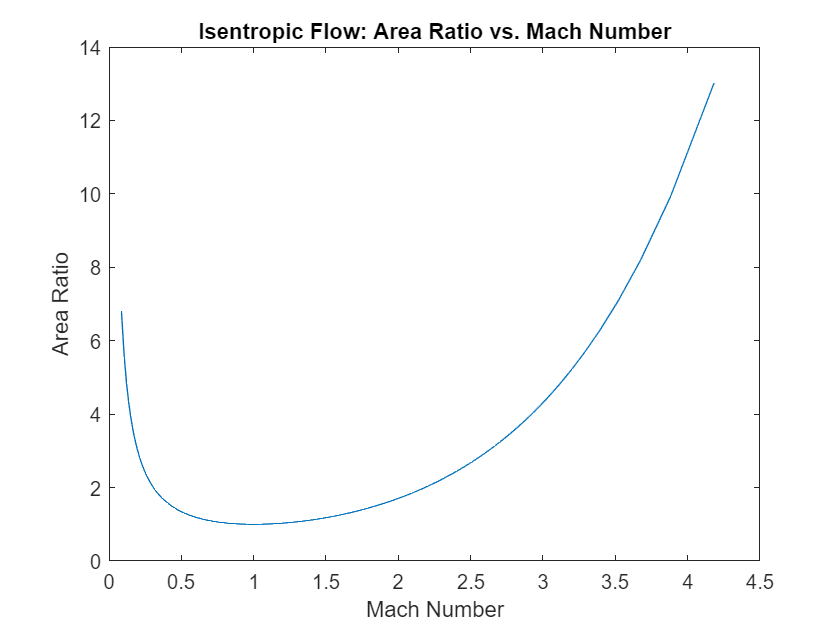

Elapsed time is 4.927799 seconds.


isentropic();

  reactor1 Zero-dimensional kinetics: adiabatc, constant pressure.
 
  This example illustrates how to use class 'Reactor' for zero-dimensional
  kinetics simulations. Here the parameters are set so that the reactor is
  adiabatic and very close to constant pressure.

CPU time = 0.34375


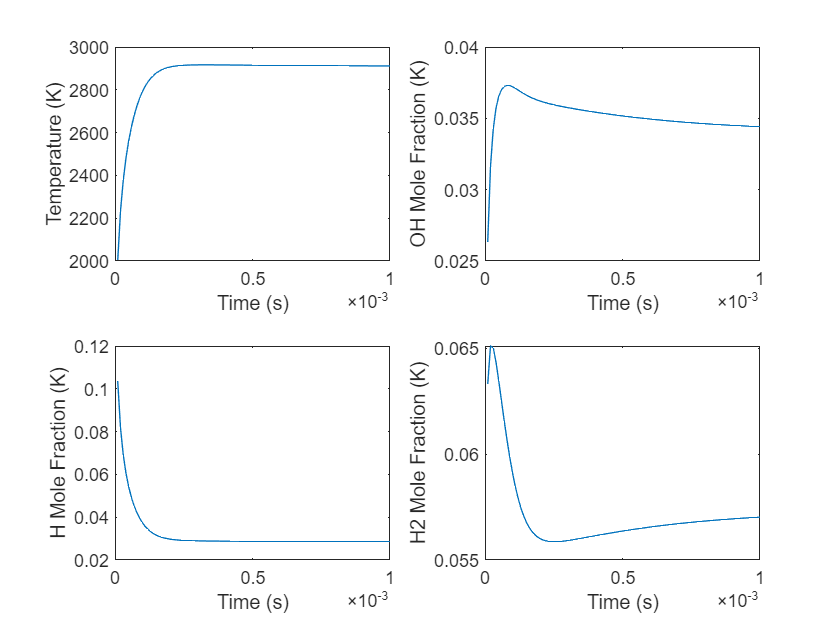

Elapsed time is 4.036645 seconds.


reactor1();

  reactor2 Zero-dimensional kinetics: adiabatic, constant volume.
 
     This example illustrates how to use class 'Reactor' for
     zero-dimensional kinetics simulations. Here the parameters are
     set so that the reactor is adiabatic and constant volume.

CPU time = 0.26562


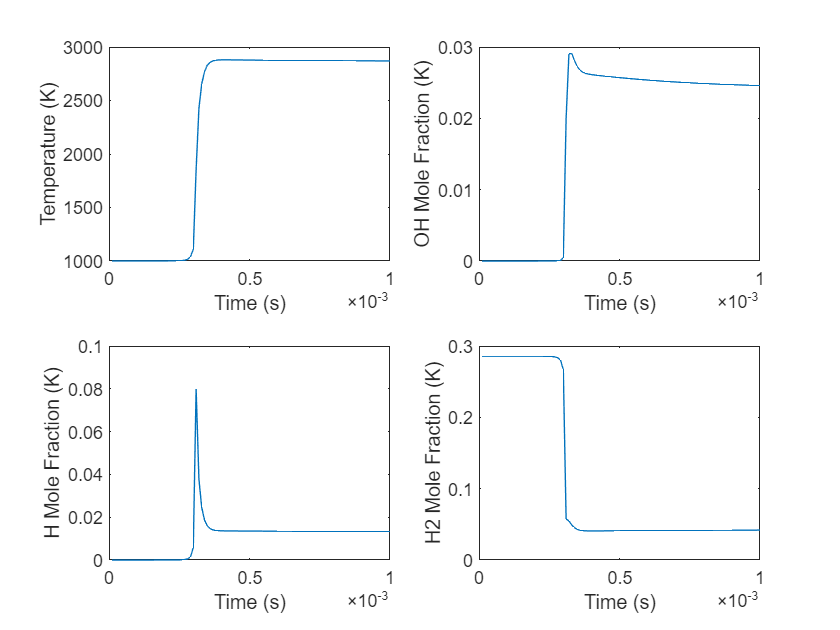

Elapsed time is 3.824051 seconds.


reactor2();

  surfreactor Zero-dimensional reactor with surface chemistry
 
     This example illustrates how to use class 'Reactor' for
     zero-dimensional simulations including both homogeneous and
     heterogeneous chemistry.

CPU time = 0.60938


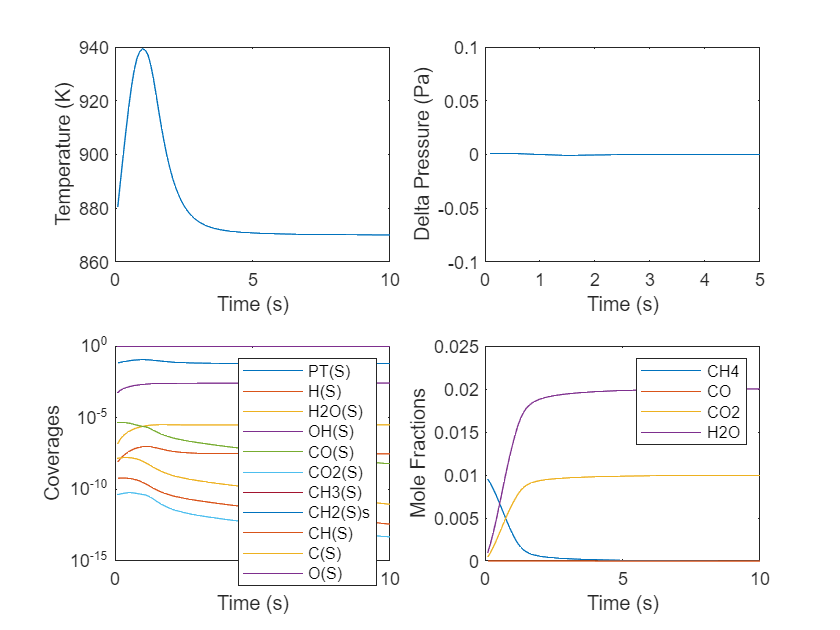

Elapsed time is 7.317050 seconds.


surfreactor;

 
   periodic_cstr - A CSTR with steady inputs but periodic interior state.
 
   A stoichiometric hydrogen/oxygen mixture is introduced and reacts to produce
   water. But since water has a large efficiency as a third body in the chain
   termination reaction
 
          H + O2 + M = HO2 + M
 
   as soon as a significant amount of water is produced the reaction
   stops. After enough time has passed that the water is exhausted from
   the reactor, the mixture explodes again and the process
   repeats. This explanation can be verified by decreasing the rate for
   reaction 7 in file 'h2o2.yaml' and re-running the example.
 
   Acknowledgments: The idea for this example and an estimate of the
   conditions needed to see the oscillations came from Bob Kee,
   Colorado School of Mines



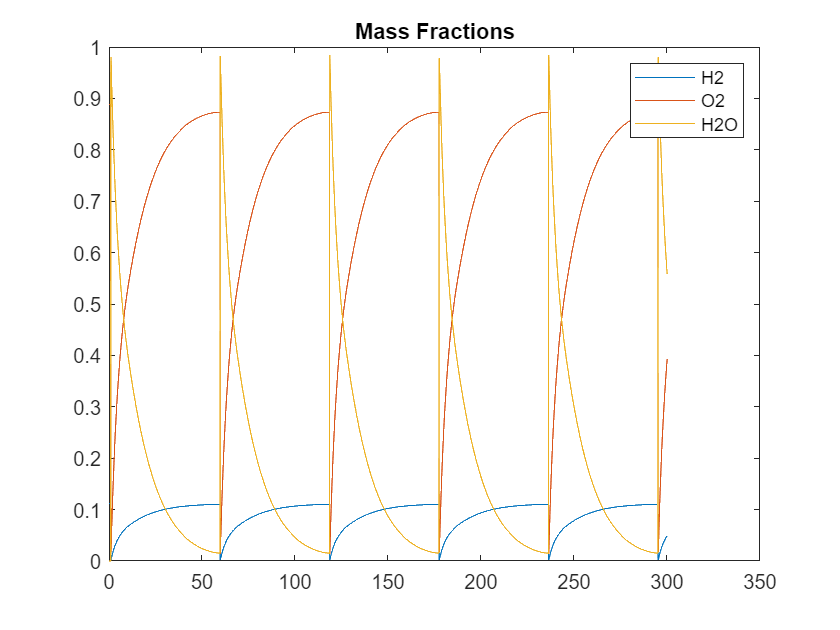

Elapsed time is 6.048975 seconds.


periodic_cstr;

  General_Plug_Flow_Reactor (PFR) - to solve PFR equations for reactors
 
     This code snippet is to model a constant area and varying area
     (converging and diverging) nozzle as Plug Flow Reactor with given
     dimensions and an incoming gas. The pressure is not assumed to be
     constant here, as opposed to the Python Version of the
     Plug Flow Reactor model.
 
     The reactor assumes that the flow follows the Ideal Gas Law.
 
     The governing equations used in this code can be referenced at:
     *S.R Turns, An Introduction to Combustion - Concepts and Applications,
     McGraw Hill Education, India, 2012, 206-210.*
 
     The current example is written for methane combustion, but can be readily
     adapted for other chemistries.
 
     Developed by Ashwin Kumar/Dr.Joseph Meadows (mgak@vt.edu/jwm84@vt.edu) on 3-June-2020
     Research Assistant/Assistant Professor
     Advanced Propulsion and Power Laboratory
     Virginia Tech

Solvin

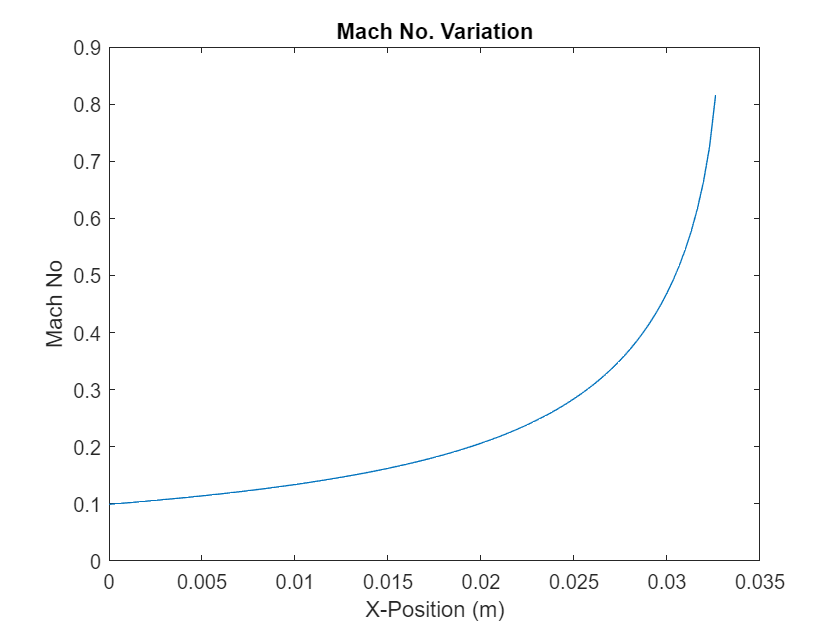

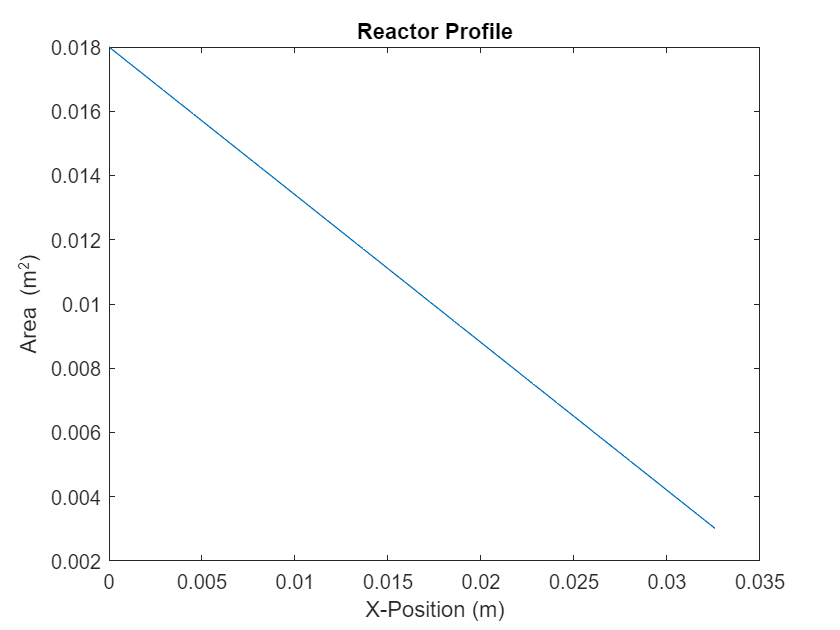

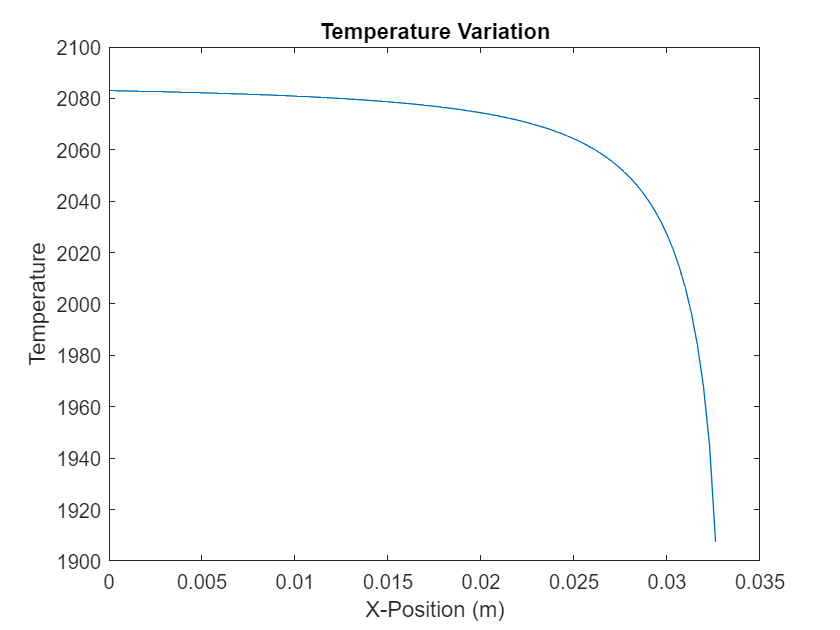

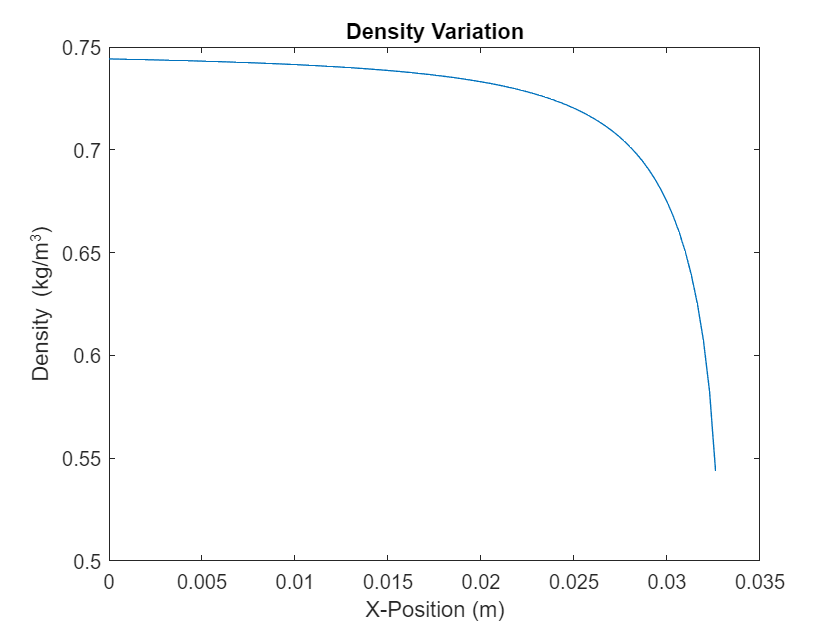

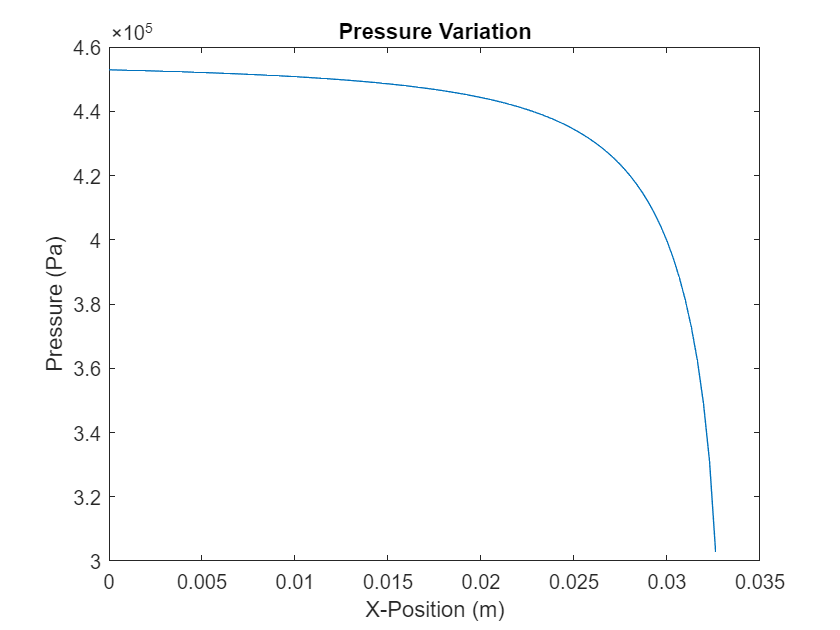

Elapsed time is 25.747648 seconds.


plug_flow_reactor

  lithium_ion_battery
 
  This example file calculates the cell voltage of a lithium-ion battery
  at given temperature, pressure, current, and range of state of charge (SOC).
 
  The thermodynamics are based on a graphite anode and a LiCoO2 cathode,
  modeled using the 'BinarySolutionTabulatedThermo' class.
  Further required cell parameters are the electrolyte ionic resistance, the
  stoichiometry ranges of the active materials (electrode balancing), and the
  surface area of the active materials.
 
  The functionality of this example is presented in greater detail in the
  reference (which also describes the derivation of the
  BinarySolutionTabulatedThermo class):
 
  Reference:
  M. Mayur, S. C. DeCaluwe, B. L. Kee, W. G. Bessler, “Modeling and simulation
  of the thermodynamics of lithium-ion battery intercalation materials in the
  open-source software Cantera,” Electrochim. Acta 323, 134797 (2019),
  

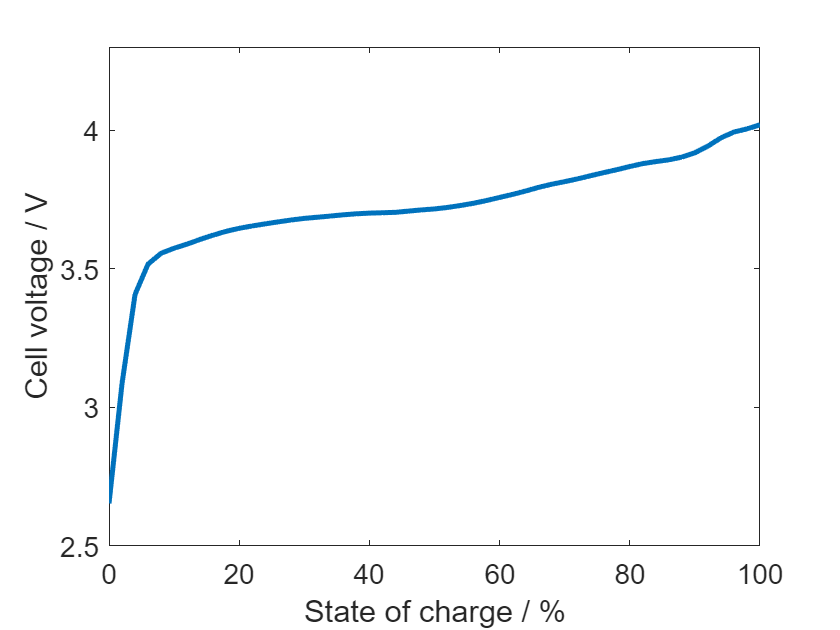

Elapsed time is 4.566442 seconds.


lithium_ion_battery

rankine(300.0, 2.0*oneatm, 0.8, 0.7)

  This example computes the efficiency of a simple vapor power cycle.



ans = 4.0307e+05

  prandtl1  Prandtl number for an equilibrium H/O gas mixture.
 
     This example computes and plots the Prandtl number for a
     hydrogen / oxygen mixture in chemical equilibrium for P = 1
     atm and a range of temperatures and elemental O/(O+H) ratios.

CPU time = 4.0781


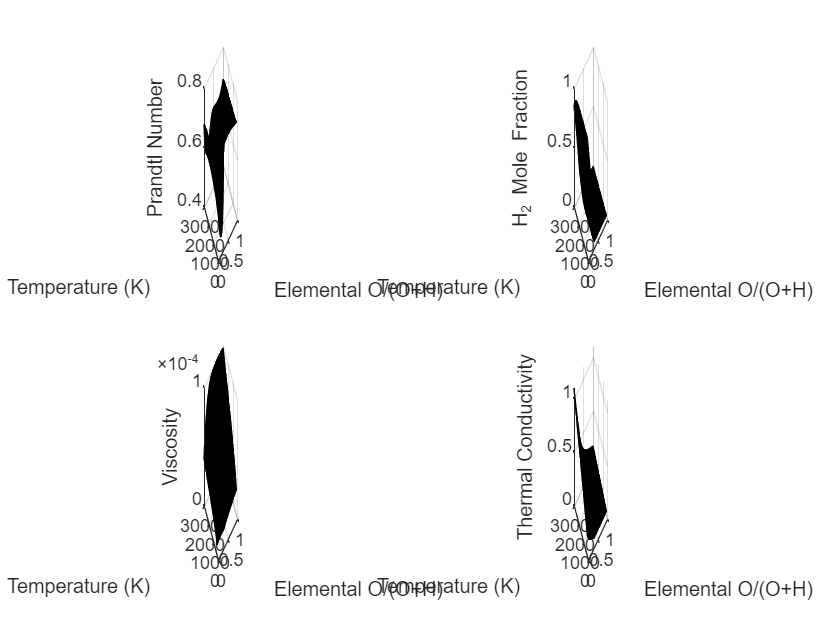

Elapsed time is 8.425675 seconds.


prandtl1();

  prandtl2  Prandtl number for an equilibrium H/O gas mixture.
 
     This example does the same thing as prandtl1, but using
     the multicomponent expression for the thermal conductivity.

CPU time = 4.375


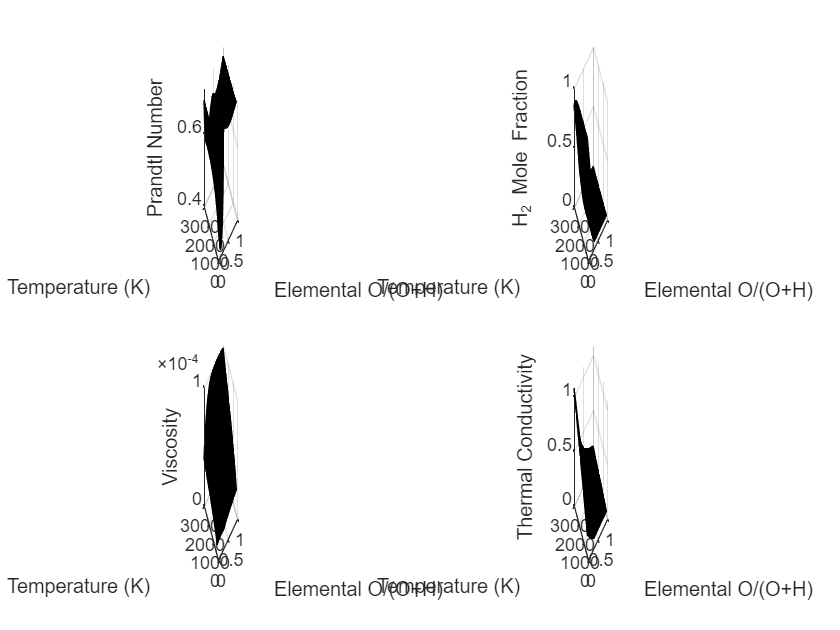

Elapsed time is 8.971889 seconds.


prandtl2();

  flame1 - A burner-stabilized flat flame
 
     This script simulates a burner-stablized lean hydrogen-oxygen flame
     at low pressure.

 
Enabling the energy equation...
Elapsed CPU time:      1.812


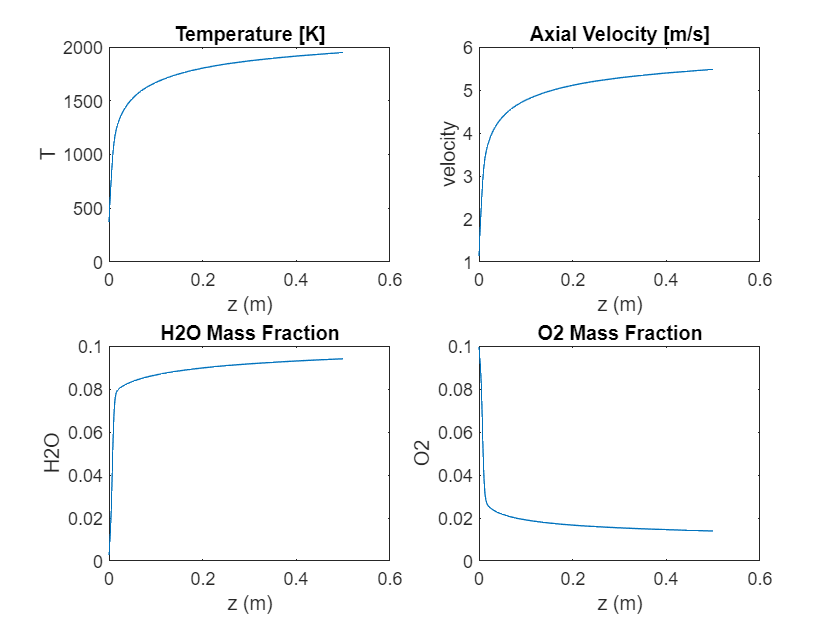

Elapsed time is 4.100816 seconds.


flame1;

  flame2 - An axisymmetric stagnation-point non-premixed flame
 
     This script simulates a stagnation-point ethane-air flame.

 
Enabling the energy equation...
Elapsed CPU time:      5.297


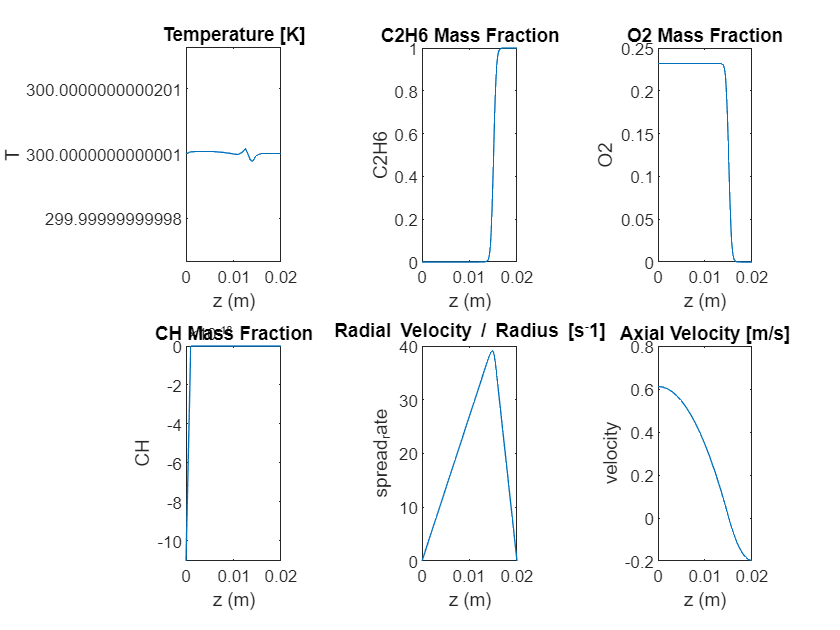

Elapsed time is 7.491872 seconds.


flame2;

  Catalytic combustion of a stagnation flow on a platinum surface
 
  This script solves a catalytic combustion problem. A stagnation flow
  is set up, with a gas inlet 10 cm from a platinum surface at 900
  K. The lean, premixed methane/air mixture enters at ~ 6 cm/s (0.06
  kg/m2/s), and burns catalytically on the platinum surface. Gas-phase
  chemistry is included too, and has some effect very near the
  surface.
 
  The catalytic combustion mechanism is from Deutschman et al., 26th
  Symp. (Intl.) on Combustion,1996 pp. 1747-1754

 
Enabling the energy equation...
Elapsed CPU time:      4.891


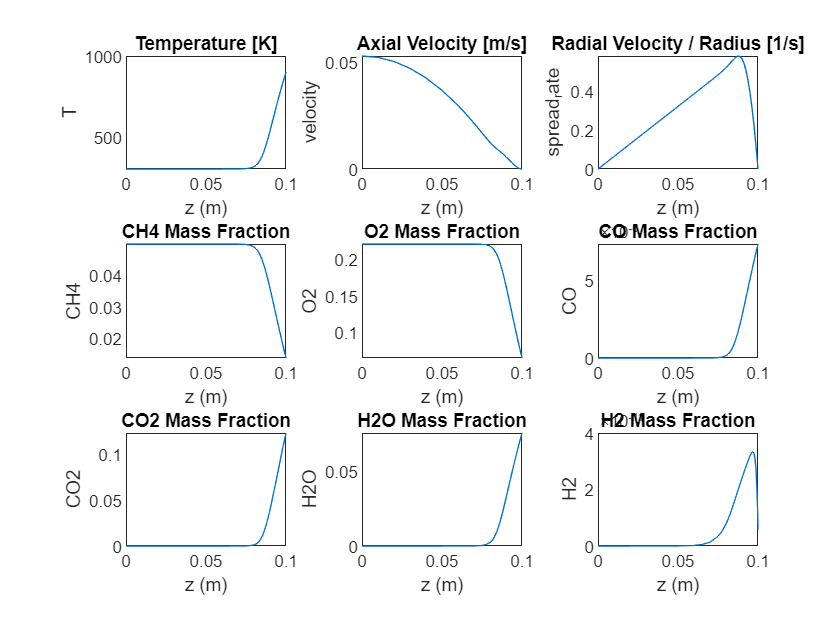

catcomb;

  diff_flame - An opposed-flow diffusion flame.
  This example uses the CounterFlowDiffusionFlame function to solve an
  opposed-flow diffusion flame for Ethane in Air. This example is the same
  as the diffusion_flame.py example without radiation.

 
Enabling the energy equation...
Elapsed CPU time:      20.27


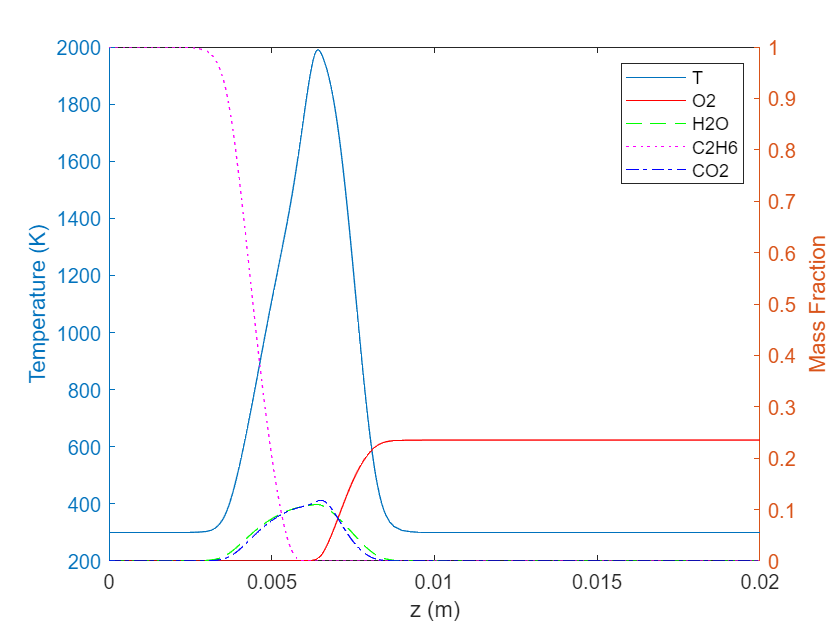

Elapsed time is 22.704946 seconds.


diff_flame;

   ignite_hp  Solves the same ignition problem as 'ignite', but uses  
   function conhp instead of reactor.

57 successful steps
0 failed attempts
148 function evaluations
1 partial derivatives
13 LU decompositions
70 solutions of linear systems
CPU time = 1.6875


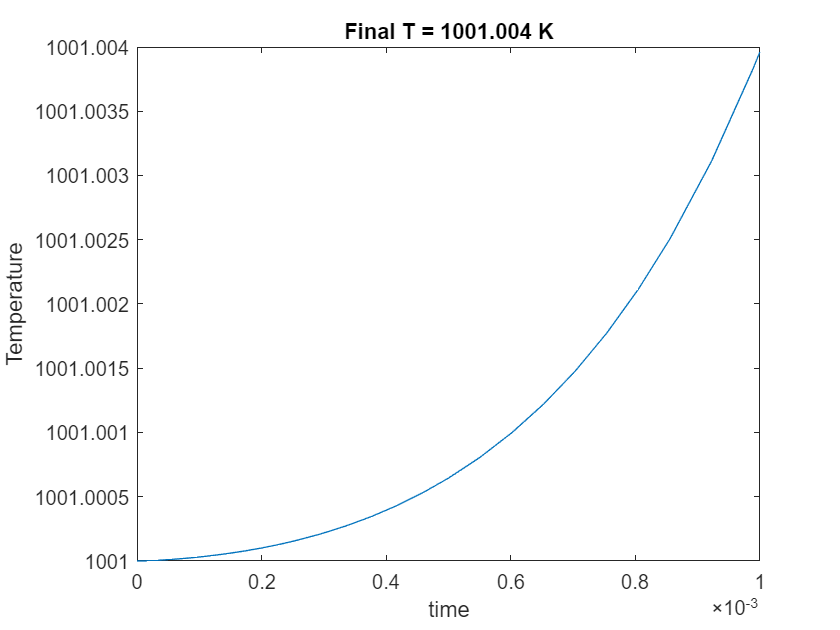

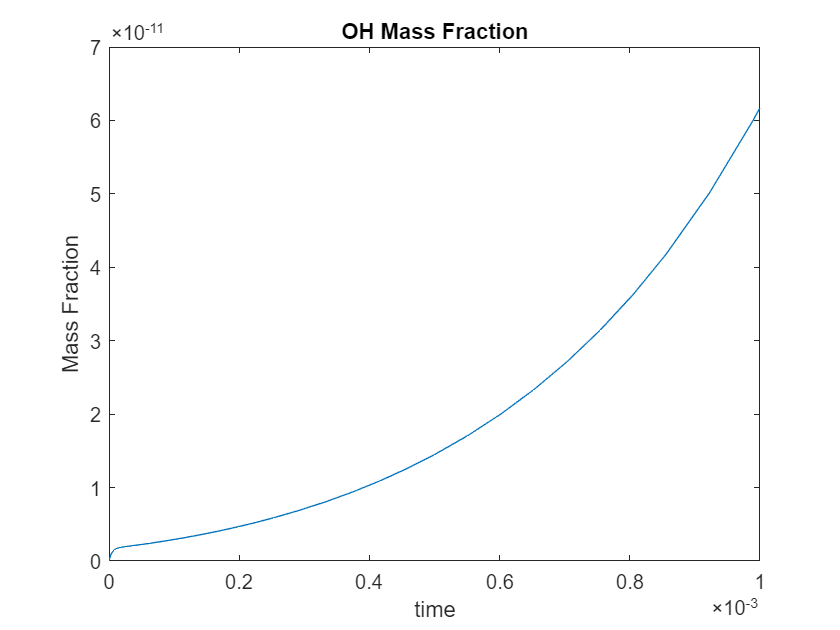

Elapsed time is 5.439213 seconds.


ignite_hp

   ignite_uv  Solves the same ignition problem as 'ignite2', except
   function conuv is used instead of reactor.

57 successful steps
0 failed attempts
149 function evaluations
1 partial derivatives
13 LU decompositions
70 solutions of linear systems
CPU time = 1.5312


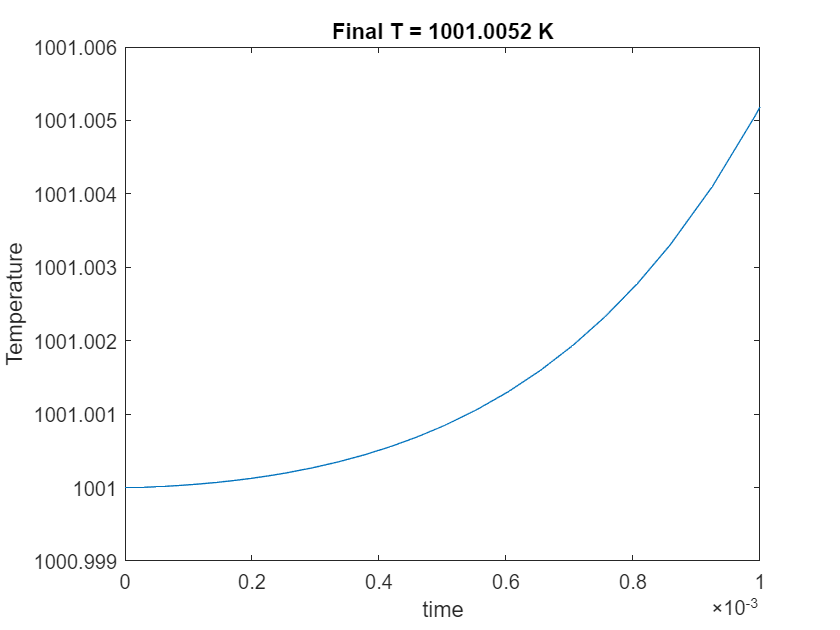

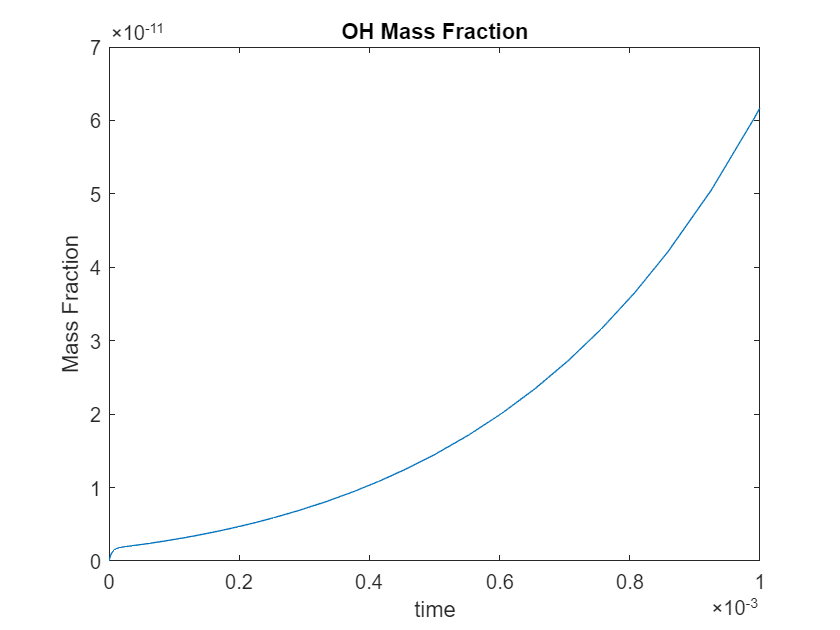

Elapsed time is 5.148851 seconds.


ignite_uv

clear all
close all
cleanup
UnloadCantera

Cantera has been unloaded


Elapsed time is 17.079524 seconds.
